# Lab 6: Image Segmentation through K-Means

The goal of image segmentation is to partition an image into regions, each of which have a resonably homogenous visual appearance or which corresponds to similar objects or parts of an object. Each pixel in an image is a point in a 3-dimensional space comprising of the intensities of the red, blue, and green channels, and our segmentation algorithm simply treats each pixel in the image as a separate data point. We illustrate the result of running Kmeans, for any particular value of K, by re-drawing the image replacing each pixel vector with the (R,G,B} intensity triplet given by the centroid to with that pixel has been assigned. Results for various values of K based on example elephant.jpg are shown as follow. 

You have two images — elephant.jpg and eiffel.jpg, on which you will be running your K-Means code.

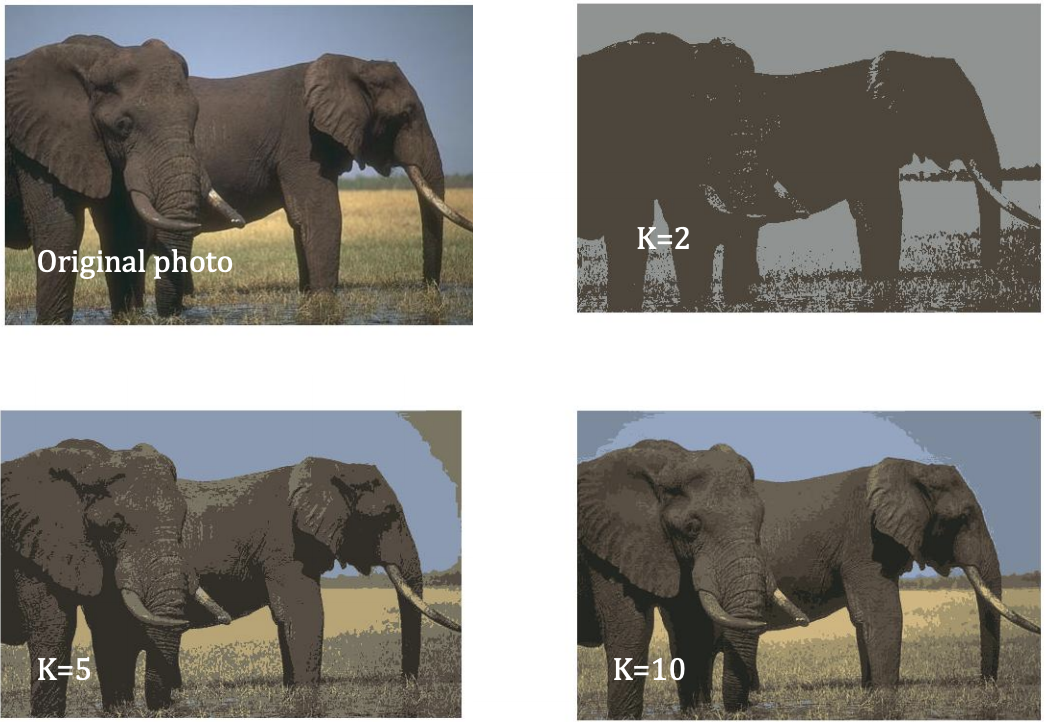

Figure 1. Segmentation of the image into different segments based on K-Means algorithm

## K-Means Implementation

## Step 1: K-Means Algorithm

Write your code in the file "KMeans.m" included in the folder. Your *KMeans*(Image,K,maxIter) function takes in 3 inputs — **1) Image**, to run K-Means segmentation on, **2) K**, denoting the number of segments you wish to classify the pixels of the image image into, **3) maxIter**, specifying the upper bound on the number of iterations before the code terminates. The *KMeans *function should ouput the following — 1) final set of coordinates of the K centroids, 2) final segmented image based on the K centroids. 

%initialize
clear
close all


Image_elephant = 'elephant.jpg';
Image_tower = 'eiffel.jpg';
[row_e, col_e, rgb] = size(imread(Image_elephant));
[row_t, col_t, rgb] = size(imread(Image_tower));
maxIter = 100;
K = [2,5,10];


## Step 2: Testing 

Load elephant.jpg and eiffel.jpg images and run K-Means, with K = 2, K = 5 and K = 10 on both the images. Generate ***two*** figures, for elephant and eiffel images, with each figure having 4 subplots with the original image and segmented images (see Fig. 1).

%elephant
[centroid_coord_1, segmented_image_1] = KMeans(Image_elephant,K(1),maxIter);
[centroid_coord_2, segmented_image_2] = KMeans(Image_elephant,K(2),maxIter);
[centroid_coord_3, segmented_image_3] = KMeans(Image_elephant,K(3),maxIter);
%tower
[centroid_coord_11, segmented_image_11] = KMeans(Image_tower,K(1),maxIter);
[centroid_coord_22, segmented_image_22] = KMeans(Image_tower,K(2),maxIter);
[centroid_coord_33, segmented_image_33] = KMeans(Image_tower,K(3),maxIter);


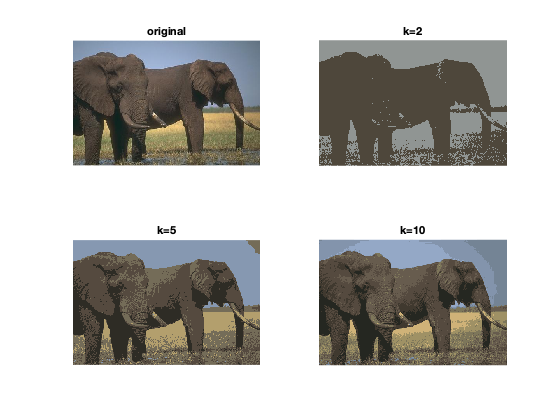

figure(1)
subplot(2,2,1);
imshow(Image_elephant);
title('original');

subplot(2,2,2);
imshow(segmented_image_1);
title('k=2');

subplot(2,2,3);
imshow(segmented_image_2);
title('k=5');

subplot(2,2,4);
imshow(segmented_image_3);
title('k=10');

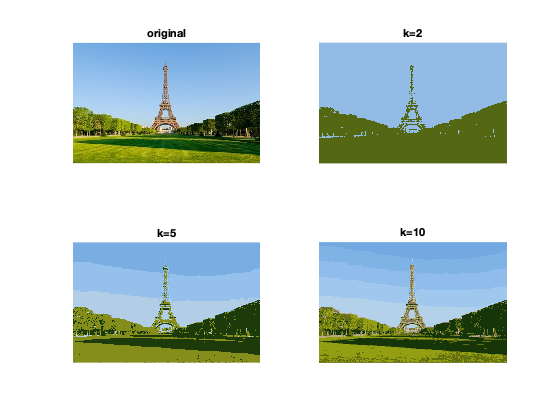

figure(2)
subplot(2,2,1);
imshow(Image_tower);
title('original');

subplot(2,2,2);
imshow(segmented_image_11);
title('k=2');

subplot(2,2,3);
imshow(segmented_image_22);
title('k=5');

subplot(2,2,4);
imshow(segmented_image_33);
title('k=10');

## Step 3: Comparison with MATLAB K-Means

Now use the inbuilt MATLAB *kmeans* function and compare the output for the elephant.jpg image **only.** You code should generate*** one ***figure with the original image, segmented image from your K-Means code with K = 5, segmented image from the MATLAB K-Means function with K = 5.

% figure(3)
% subplot(2,2,1);
% imshow(Image_elephant);
% title('original');
% 
% subplot(2,2,2);
% imshow(matlab_kmean(Image_elephant,2,maxIter,row_e,col_e));
% title('k=2');
% 
% subplot(2,2,3);
% imshow(matlab_kmean(Image_elephant,5,maxIter,row_e,col_e));
% title('k=5');
% 
% subplot(2,2,4);
% imshow(matlab_kmean(Image_elephant,10,maxIter,row_e,col_e));
% title('k=10');

% figure(4)
% subplot(2,2,1);
% imshow(Image_tower);
% title('original');
% 
% subplot(2,2,2);
% imshow(matlab_kmean(Image_tower,2,maxIter,row_t,col_t));
% title('k=2');
% 
% subplot(2,2,3);
% imshow(matlab_kmean(Image_tower,5,maxIter,row_t,col_t));
% title('k=5');
% 
% subplot(2,2,4);
% imshow(matlab_kmean(Image_tower,10,maxIter,row_t,col_t));
% title('k=10');

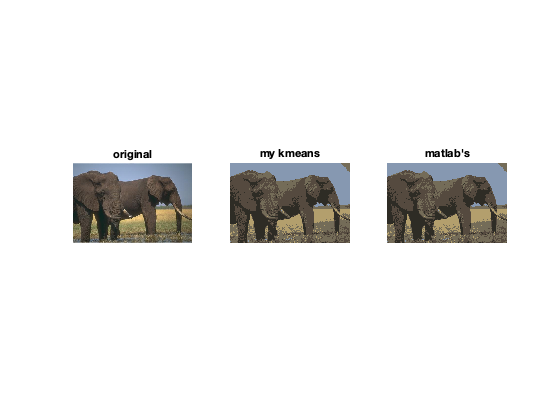

figure(5)
subplot(1,3,1);
imshow(Image_elephant);
title('original');

subplot(1,3,2);
imshow(segmented_image_2);
title('my kmeans');

subplot(1,3,3);
imshow(matlab_kmean(Image_elephant,5,maxIter,row_e,col_e));
title('matlab''s');

## Step 4: Code Optimization (Optional)

Generate the times it takes to run your K-Means and the MATLAB K-Means function with K = 5 on the elephant image. **Print **the runtimes. Try optimizing ***your ***K-Means code to generate the segmented image within the order of a few seconds, in comparison to the MATLAB K-Means computation times.

tic;
[centroid_coord_2, segmented_image_2] = KMeans(Image_elephant,K(2),maxIter);
toc;

Elapsed time is 2.787528 seconds.


tic;
figure_test = matlab_kmean(Image_elephant,5,maxIter,row_e,col_e);
toc;

Elapsed time is 2.936337 seconds.


## ***Attached function for step 3 by using matlab's kmeans***

function figure = matlab_kmean(Image,K,maxIter,row,col)
    img(:,:,:) = double(imread(Image));
    R = reshape(img(:,:,1),[],1);
    G = reshape(img(:,:,2),[],1);
    B = reshape(img(:,:,3),[],1);
    img_matrix = [R,G,B];
    [idx,centroid] = kmeans(img_matrix, K,'MaxIter',maxIter);
    img_matrix_with_idx = [img_matrix,idx];
    row_num = length(idx);
    for i = 1:K
        for j = 1:row_num
           if (img_matrix_with_idx(j,4) == i)
              img_matrix_with_idx(j,1:3) = centroid(i,:);
           end
        end    
    end
    figure = uint8(reshape(img_matrix_with_idx(:,1:3),row,col,3));    
end